# Kinematics - Jacobian

clc; clear; close all
load_data_kinematics;

## Motion data

Ttot = 5;               % total time of motion = 5 seconds
nPoints = 100;          % number of points
dT = Ttot/(nPoints-1);  % time step

Qini = [median(pos_limits(1:2)); median(pos_limits(3:4)); median(pos_limits(5:6))];
Qfin = [pos_limits(2); pos_limits(4); pos_limits(6)];

dq1 = Qfin(1)-Qini(1);    % alpha
dq2 = Qfin(2)-Qini(2);    % beta
dq3 = Qfin(3)-Qini(3);    % gamma

## Symbolic computation of the Jacobian

syms l1a l1b l1c l2 l3 tilt_angle q1_sym(t) q2_sym(t) q3_sym(t) q1p_sym(t) q2p_sym(t) q3p_sym(t)
Qsymb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t)];
Qp_symb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t); q1p_sym(t); q2p_sym(t); q3p_sym(t)];

% Compute symbolic jacobian and its derivative w.r.t. time
[~,J_symb] = jac_symb;
[~,Jp_symb] = jacP_symb;

## Initialize variables

nCoord = 18;

Q = zeros(3,nPoints);
Qp = zeros(3,nPoints);
Qpp = zeros(3,nPoints);

S = zeros(nCoord,nPoints);
Sp = zeros(nCoord,nPoints);
Spp = zeros(nCoord,nPoints);

pos = zeros(1,nPoints);     % curvilinear abscissa along the trajectory

## Cycle for each time step

tic

tt = linspace(0,Ttot,nPoints);

for i = 1:nPoints
    
    fprintf("progression: %.2f %% - elapsed time: %.2f seconds\n", i/nPoints*100, toc)
    
    %% KINEMATICS %%
    
    % JOINT COORDINATES
    [q1,q1p,q1pp] = cycloidal(tt(i),Ttot,Qini(1),dq1);
    [q2,q2p,q2pp] = cycloidal(tt(i),Ttot,Qini(2),dq2);
    [q3,q3p,q3pp] = cycloidal(tt(i),Ttot,Qini(3),dq3);
    
    Q(:,i) = [q1; q2; q3];
    Qp(:,i) = [q1p; q2p; q3p];
    Qpp(:,i) = [q1pp; q2pp; q3pp];
    
    
    % COORDINATES THROUGH DIRECT KINEMATICS
    [~,Scell] = dir_kin(num2cell(Q(:,i)),L,angle);
    S(:,i) = cell2mat(Scell);

    % CONVERT FROM SYMBOLIC TO NUMERICAL VALUES
    J = double(subs(J_symb,Qsymb,[L'; angle; Q(:,i)]));
    Jp = double(subs(Jp_symb,Qp_symb,[L'; angle; Q(:,i); Qp(:,i)]));
    
    % VELOCITY ARRAY
    Sp(:,i) = J*Qp(:,i);    
    
    % ACCELERATION ARRAY
    Spp(:,i) = J*Qpp(:,i)+Jp*Qp(:,i);
    
    % POSITION OF THE GRIPPER ALONG THE TRAJECTORY
    % (velocity and acceleration are computed afterwards using diff()/dT)
    pos(i) = norm(S(1:3,i) - S(1:3,1));
        
    %%%%% END KINEMATICS %%%%%

end

progression: 1.00 % - elapsed time: 0.02 seconds
progression: 2.00 % - elapsed time: 0.31 seconds
progression: 3.00 % - elapsed time: 0.49 seconds
progression: 4.00 % - elapsed time: 0.65 seconds
progression: 5.00 % - elapsed time: 0.80 seconds
progression: 6.00 % - elapsed time: 0.97 seconds
progression: 7.00 % - elapsed time: 1.12 seconds
progression: 8.00 % - elapsed time: 1.28 seconds
progression: 9.00 % - elapsed time: 1.43 seconds
progression: 10.00 % - elapsed time: 1.61 seconds
progression: 11.00 % - elapsed time: 1.77 seconds
progression: 12.00 % - elapsed time: 1.97 seconds
progression: 13.00 % - elapsed time: 2.15 seconds
progression: 14.00 % - elapsed time: 2.35 seconds
progression: 15.00 % - elapsed time: 2.55 seconds
progression: 16.00 % - elapsed time: 2.72 seconds
progression: 17.00 % - elapsed time: 2.88 seconds
progression: 18.00 % - elapsed time: 3.09 seconds
progression: 19.00 % - elapsed time: 3.30 seconds
progression: 20.00 % - elapsed time: 3.52 seconds
progressi

## Compute derivatives (numerical differentiation) to debug results

% GRIPPER COORDINATES
xp_diff = diff(S(1,:),[],2)/dT;
yp_diff = diff(S(2,:),[],2)/dT;
zp_diff = diff(S(3,:),[],2)/dT;

xpp_diff = diff(Sp(1,:),[],2)/dT;
ypp_diff = diff(Sp(2,:),[],2)/dT;
zpp_diff = diff(Sp(3,:),[],2)/dT;

% GRIPPER VELOCITY AND ACCELERATION ALONG THE TRAJECTORY
vel = diff(pos)/dT;
acc = diff(vel)/dT;

% JOINT COORDINATES
Qp_diff = diff(Q,[],2)/dT;
Qpp_diff = diff(Qp,[],2)/dT;

## Plot results

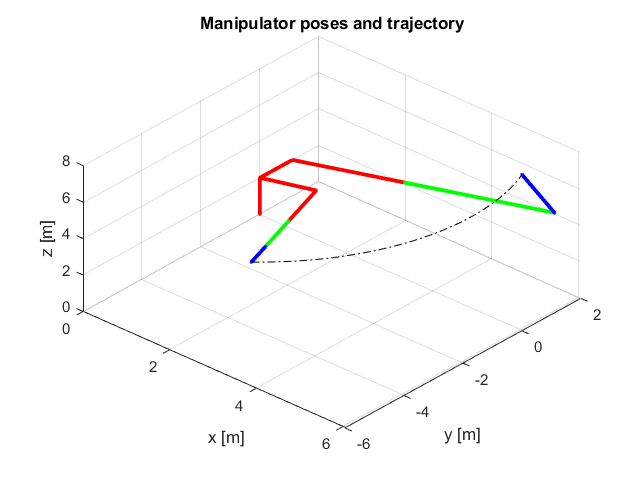

% PLOT INITIAL AND FINAL CONFIGURATIONS OF THE WRIST + TRAJECTORY
figure
set(gcf,'name','3D representation xyz')
p1 = plot_robot(num2cell(Qini),L,angle,gcf);    % Initial configuration
hold on
p2 = plot_robot(num2cell(Qfin),L,angle,gcf);    % Final configuration
hold on
p3 = plot3(S(end-2,:),S(end-1,:),S(end,:),'-.k');
grid on
title('Manipulator poses and trajectory');
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
view(27,26) % Point of view: (azimut,elevation)